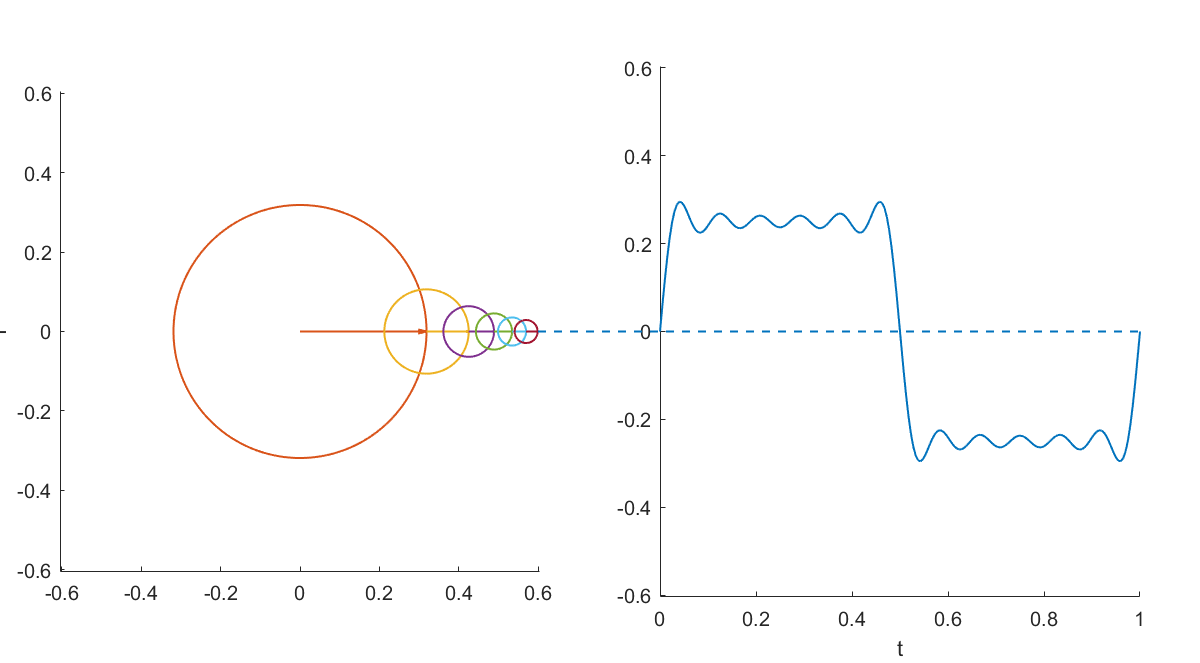

func = "square";
Nmodes = 6; % Number of Fourier modes
Npoints = 200; % Animation/plot resolution
Nperiods = 1; % Number of periods to show
showCircles = true; % Show the phasor paths as circles
 

plotFourierPhasors(Nmodes,func,Npoints,Nperiods,showCircles);

**Helper functions**

function updateCircle(pHandle,r,c,theta)
    pHandle.XData = c(1) + r*cos(theta);
    pHandle.YData = c(2) + r*sin(theta);
end

function pFig = figPos(ax,p)

    % Shifted so that the origin is at the lower-left corner
    x = p(1)-ax.XLim(1);
    y = p(2)-ax.YLim(1);
    
    % Compute the position of the point in the figure
    axUnits = ax.Units;
    ax.Units = 'normalized';
    xFig = x*(ax.Position(3))/(ax.XLim(2) - ax.XLim(1)) + ax.Position(1);
    yFig = y*(ax.Position(4))/(ax.YLim(2) - ax.YLim(1)) + ax.Position(2);
    
    pFig = [xFig,yFig];
    ax.Units = axUnits;
end

function plotFourierPhasors(Nmodes,func,Npoints,Nperiods,showCircles)

    % Settings
    colors = lines(100);
    lw = 1;

    % variables
    c = zeros(Nmodes,2);
    t = linspace(0,Nperiods,Npoints);

    % Select from the available functions
    symmetry = "odd";
    if(strcmpi(func,"square"))
        n = 1:2:(Nmodes*2);
        r = 1./(n*pi);
    elseif(strcmpi(func,"triangle"))
        n = 1:2:(Nmodes*2);
        r = 8*(-1).^((n-1)/2)./(pi^2*n.^2);
    elseif(strcmpi(func,"sawtooth"))
        n = 1:Nmodes;
        r = -1./(n*pi);
    elseif(strcmpi(func,"rectified"))
        symmetry = "even";
        n = 1:(Nmodes);
        r = -4./(pi*(4*n.^2 - 1));
        c(1,:) = [0,2/pi];
    else
        error("You must provide a valid name for the function.")
    end

    % Axis limits
    axisLims1 = [-1,1,-1,1]*sum(abs(r))*1.01;
    axisLims2 = [t(1),t(end),axisLims1(3:4)];

    axisLims1(3:4) = axisLims1(3:4) + c(1,2);
    axisLims2(3:4) = axisLims2(3:4) + c(1,2);

    
    % Set up the figure
    figure('position',[0,0,1000,500])%,'visible','on')
    ax1 = subplot('position',[0.05,0.1,0.4,0.8]);
    axis equal
    axis(axisLims1)
    axis manual
    thetaCirc = linspace(0,2*pi,200);
    hold(ax1,"on")
    for k = 1:Nmodes
        circHandles{k} = plot(ax1,0,0,'color',colors(k+1,:),'linewidth',lw);   
        lineHandles{k} = quiver(ax1,0,0,0,0,'color',colors(k+1,:),'linewidth',lw,"AutoScale","off");   
    end
    hold(ax1,"off")
    ylabel("f")
    
    ax2 = subplot('position',[0.55,0.1,0.4,0.8]);
    signalHandle = plot(ax2,0,0,'color',colors(1,:),'linewidth',lw);
    axis manual
    axis(ax2,axisLims2)
    box off
    xlabel("t")
    
    crossLine = annotation('line',[0,0],[0,0],...
        "LineStyle","--","LineWidth",lw,'color',[colors(1,:),0.5]);
    
    signal = t*0;
    
    % Animate
    for j = 1:length(t)
        tj = t(j);
        
        for k = 1:Nmodes
            % Compute the x,y coordinate
            if(strcmpi(symmetry,"odd"))
                x = c(k,1) + r(k)*cos(n(k)*2*pi*tj);
                y = c(k,2) + r(k)*sin(n(k)*2*pi*tj);
            else
                x = c(k,1) + r(k)*sin(n(k)*2*pi*tj);
                y = c(k,2) + r(k)*cos(n(k)*2*pi*tj);
            end
            
            % Update the plot
            if(showCircles)
                updateCircle(circHandles{k},r(k),c(k,:),thetaCirc)
            end
            lineHandles{k}.XData = c(k,1);
            lineHandles{k}.YData = c(k,2);
            lineHandles{k}.UData = x - c(k,1);
            lineHandles{k}.VData = y - c(k,2);

            % Move the center of the next circle to the correct location
            if(k < Nmodes)
                c(k+1,:) = [x,y];
            else
                p1 = [x,y];
                signal(j,1) = y;
            end
        end
        
        % Plot the line
        signalHandle.XData = t(1:j);
        signalHandle.YData = signal(1:j);
        
        % Create annotation between the axes
        p2 = [t(j),signal(j)];
        
        p1Fig = figPos(ax1,p1);
        p2Fig = figPos(ax2,p2);
        
        crossLine.X = [p1Fig(1),p2Fig(1)];
        crossLine.Y = [p1Fig(2),p2Fig(2)];
        
        drawnow
    
    end
end